# Arduino Bicopter

## Task 1: Build

3d print necessary parts by first downloading the ".stl" files. Load them into a slicer, generate g-code (be sure to add supports to overhanging material), and print.

After printing the stand and arms, the bicopter is assembled as shown in the diagram below.

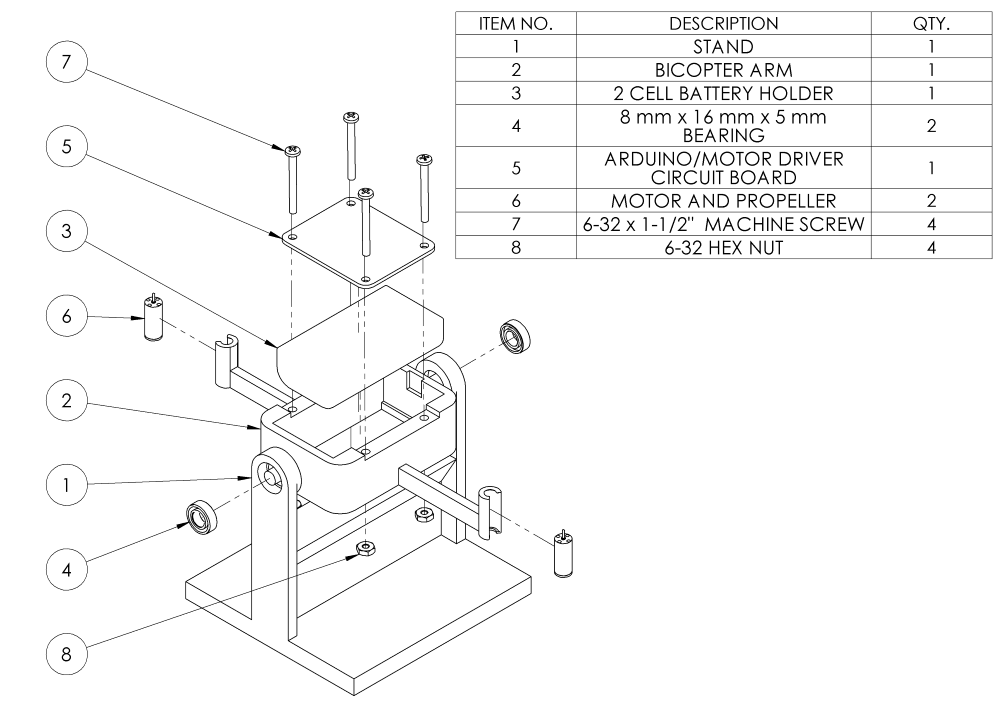

## Task 2: Preparation

Download the Simulink model **"Bicopter_OpenLoop_2022.slx",** and navigate to hardware settings.

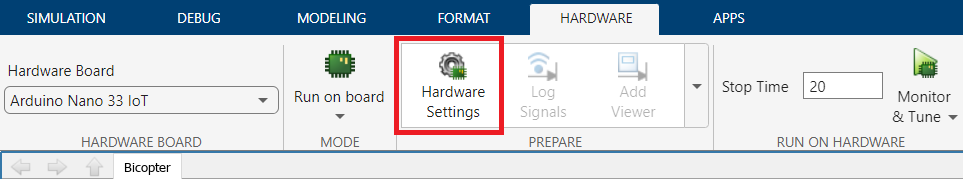

Under the settings, navigate to **Wi-Fi Properties** and enter your network credentials. If your network requires additional authentication, consider using a different network, or a personal hotspot. Ensure that your computer is connected to the same network.

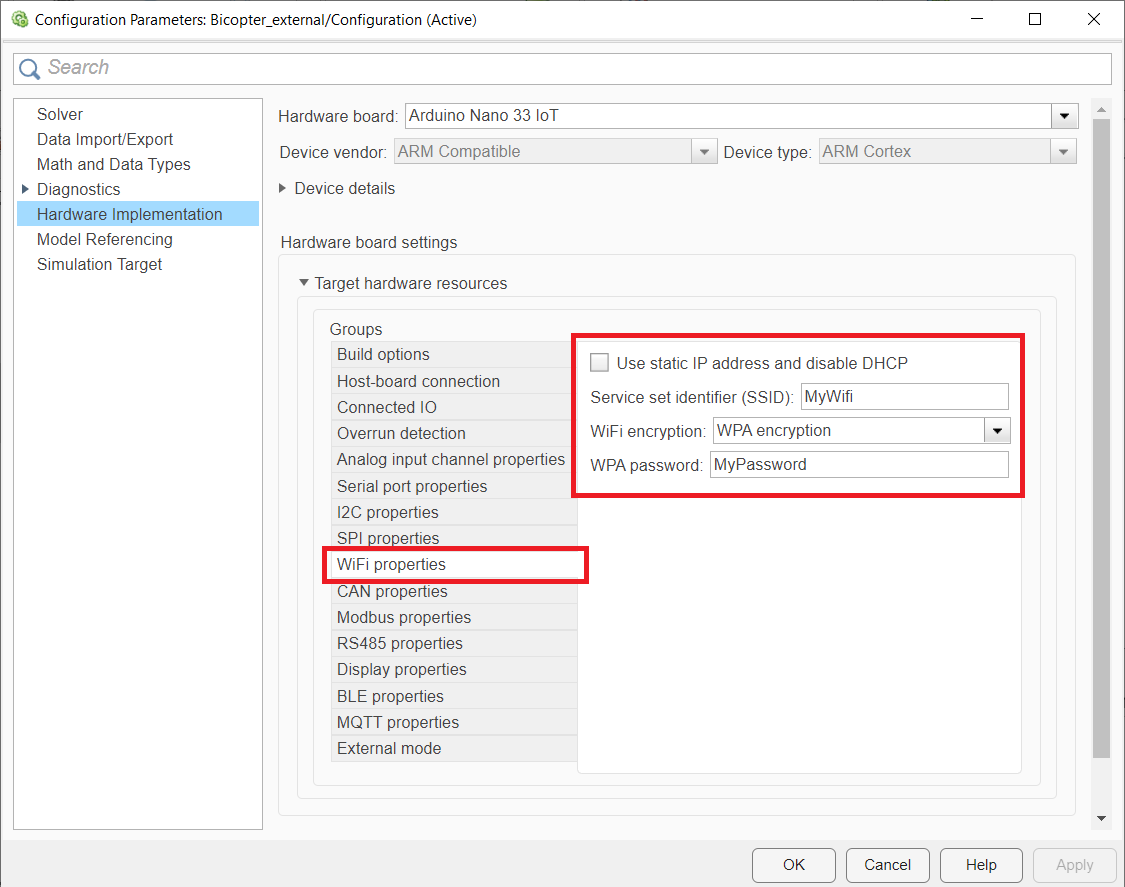

With the Arduino connected to your computer via USB, click **Build, Deploy & Start** under the **Hardware** tab.

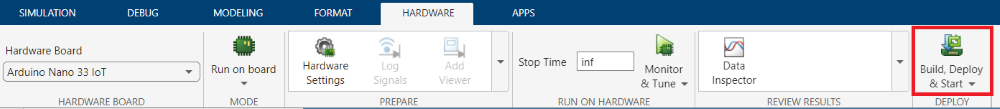

Next turn the motor driver on, and disconnect the USB cable. After programming, locate the IP address of the Arduino in the output displayed in the **Diagnostic Viewer**.

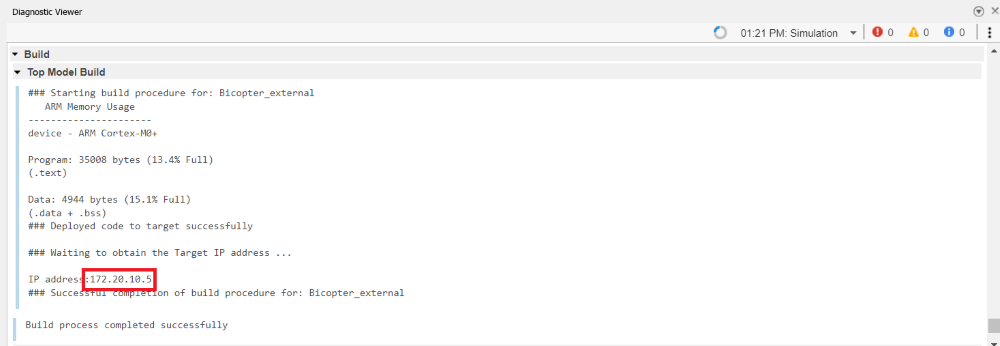

In the following code, replace `'172.20.10.5' `with your Arduino's local IP address, then run this section.

clear
close all
IPADRR='192.168.199.188' 

IPADRR = '192.168.199.188'

## Task 3: Open Loop Test

To carry ot the open-loop test, disconnect the USB cable from the device, and flip the power switch to that the device green LED is on (battery operation). At this point the program have been loaded in the Adruino. 

 The input test data can be gererated using the MATLAB funciton idinput() as follows:

dur=2000; % number of data points
Input = idinput(dur, 'rbs', [0 1/30], [-7 7]);

This generates a binary input with a frequency bandwidth from 0 to 0.1 of the Nyquist frequency and a range from -10 to 10. Once data has been generated, run the following script to send it to the Arduino and collect response. **Make sure to** **keep clear from the propellers before running the following sequence!!!**

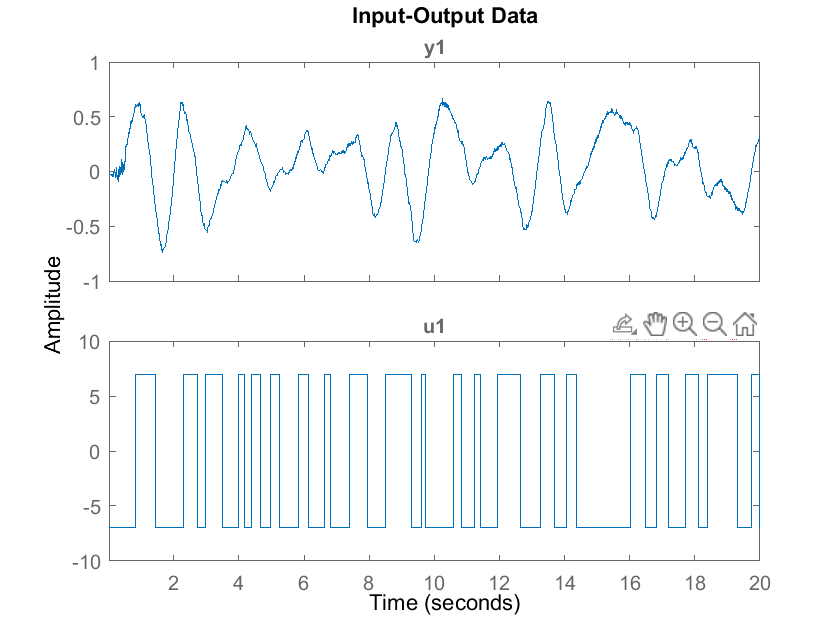

tcp = tcpclient(IPADRR,25000);
write(tcp,0,"int8");
pause(1);
write(tcp,Input,'int8');
flush(tcp);
tic
en = 0;
while en == 0
    dat = read(tcp,2,'double');
    en = dat(2);
end
D = read(tcp,2*dur,'double');
Output = D(1:2:end);
en = D(2:2:end);
T_f = toc;
clear tcp
ts = 0.01;
data = iddata(Output',Input,'Ts',ts); % Save data and plot it
close all; 
plot(data)

## Task 4: System Identification

Once the data is collected in id`data `format, the input-output data can be used to fit a model to the system. The following command fits an ARMAX  transfer function with 16 poles and zeros  to the data. We use 16 poles since we have implemented FIR of order 10. We anticipate the plant to be of 6th order. 

data=detrend(data); % remove offsets and drifts
G=arx(data,[16 16 0 ])

G =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)       
                                                          
  A(z) = 1 - 0.9821 z^-1 + 0.1566 z^-2 - 0.4161 z^-3      
          + 0.07741 z^-4 - 0.07631 z^-5 + 0.216 z^-6      
          - 0.1787 z^-7 + 0.2889 z^-8 - 0.3236 z^-9       
          + 0.7307 z^-10 - 0.4879 z^-11 - 0.03635 z^-12   
          - 0.1115 z^-13 + 0.02828 z^-14 + 0.001326 z^-15 
                                      + 0.1255 z^-16      
                                                          
                                                          
  B(z) = -0.0001786 + 0.0001685 z^-1 + 6.551e-05 z^       
          -2 - 0.0001274 z^-3 + 0.0001883 z^              
          -4 - 2.818e-05 z^-5 - 1.096e-05 z^              
          -6 + 3.434e-06 z^-7 - 2.254e-06 z^              
          -8 - 1.668e-06 z^-9 - 5.419e-05 z^              
          -10 - 0.0002337 z^-11 + 0.0002492 z^-12         
          + 0.0001118 z^-13 - 0.0002111 z^-14       

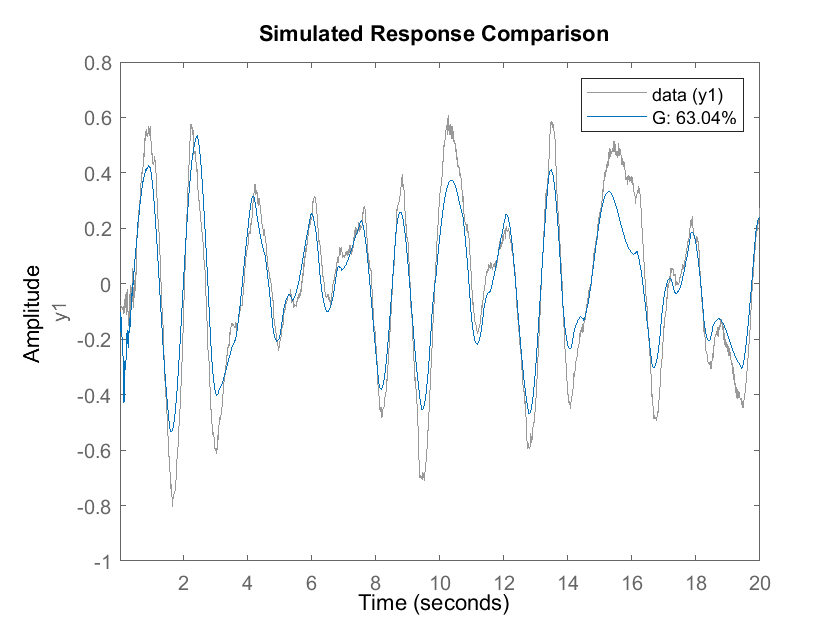

%G = tfest(data,4,3,'Ts',ts)
figure
compare(data,G)

## Task 5: Controller Design and Implementation

After fitting a model to the bicopter i/o data, we proceed with the design of a controller. Use  Tune PID Controller Live Task (or iin command mode pidtune  - see commented section below)

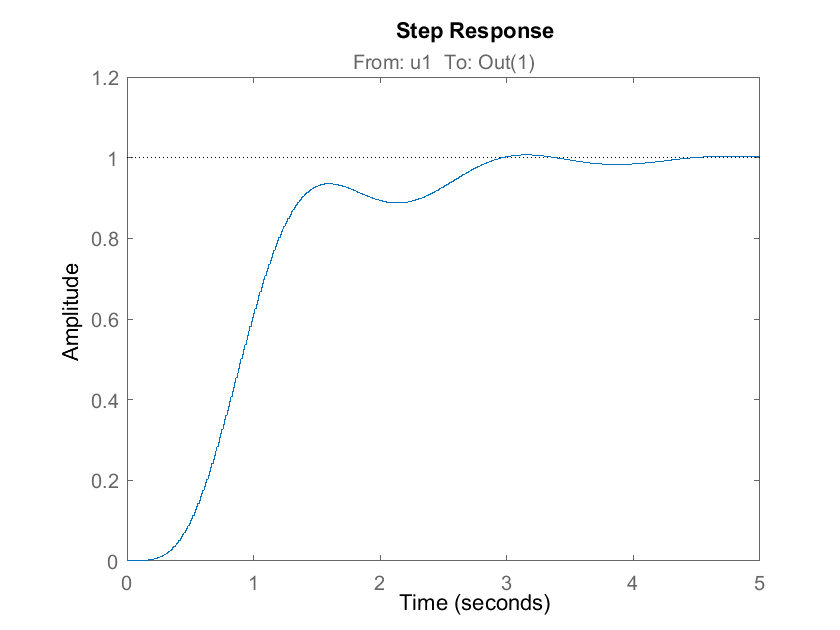

% C0 = pid(1,1,1,'Ts',ts,'IFormula','BackwardEuler','DFormula','BackwardEuler');
% C=pidtune(G,C0,1)  
% figure;step(feedback(C*G,1))

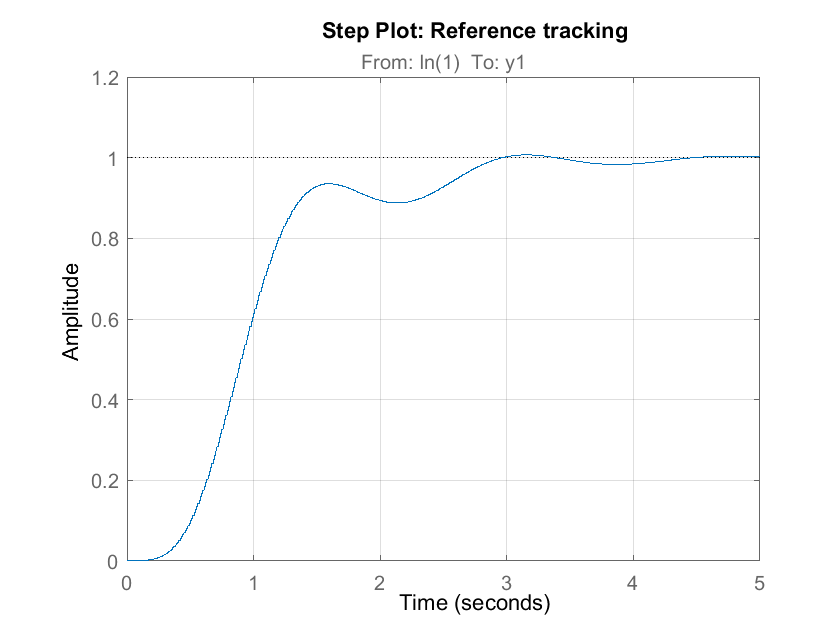

% Define options for pidtune command
opts = pidtuneOptions('PhaseMargin',60.033);
C02 = pid(1,1,1,'Ts',0.01,'IFormula','BackwardEuler');

% PID tuning algorithm for linear plant model
[C,pidInfo] = pidtune(G,C02,1,opts);

% Clear Temporary Variables
clear C02 opts

% Get desired loop response
Response = getPIDLoopResponse(C,G,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on


% Clear Temporary Variables
clear Response

## Task 6 Test the Closed Loop PID Controller

Once you have designed a controller for the bicopter, the next step is to implement it onto the Arduino. Download and open the **"Bicopter_ClosedLoop_2022_PID.slx"** Simulink model.Inside the PID block we use C.Kp, C.Ki, and C.Kd. Once the previous step has been completed, the model will use these values.  The TCP status signal is used as  reset trigger so that the controller starts from zero initial conditions when data is sent. Follow the same steps as **Task 2** (connect USB cable, set COM pots, and define your Wi-Fi network settings) in the closed-loop Simulink model  and then program the board using **Build, Deploy & Star**t button. Most likely the COM port and IP address will be the same.  Remove USB cable and turn the power switch to **ON**.   Once again, connect to the Arduino TCP server using the following command, but be sure to check that the IP address is the same as before, or update as needed.

The compliation will provide the IP address in the Diagnostic Viewer of the Simunlink model. If needed, update  the variable `IPADRR='192.168.84.188'` with your device's IP address.

Next, we can define an input array, which is the desired angle of the close-loop control. The example below generates a reference singal with 0 radians, 0.3 radians and -0.3 radians inclination. 

dur = 2500;
% Generate setpoint signal
Input = zeros(dur,1);
 Input(501:1000) = 0.3;
 Input(1501:2000) = -0.3;

Run the following code to connect to the Arduino and test the controller. **Make sure to** **keep clear from the propellers before running the following sequence!!!**

%pause(10); % wait time after after powering (starting the server in the bi-copter). This time is needed to broadcast the IP address
 tcp = tcpclient(IPADRR,25000)  % Generally the IP address remains unchanged

tcp =   tcpclient with properties:

              Address: '192.168.199.188'
                 Port: 25000
    NumBytesAvailable: 0

  Show all properties, functions


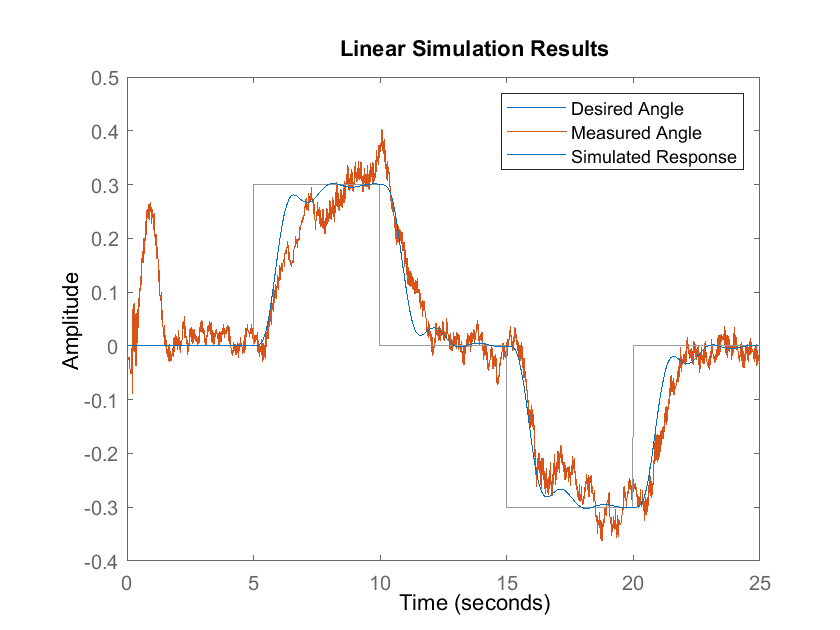

write(tcp,0,'single');
pause(1.5);
flush(tcp);
write(tcp,Input,'single');
tic
en = 0;
while en == 0
    dat = read(tcp,4,'double');
    en = dat(4);
end
D = read(tcp,4*dur,'double');
Output = D(1:4:end);
Control = D(2:4:end);
SP = D(3:4:end);
en = D(4:4:end);
T_f = toc;
clear tcp

figure
Time = 0:0.01:0.01*(dur-1);
plot(Time, SP);
hold on
plot(Time, Output);
lsim(feedback(C*G,1),SP,Time);
legend('Desired Angle','Measured Angle','Simulated Response');hold off

## Task 7: Repeat the Design with N4SID State Space Model Identification

The data from the open-loop experiment can be re-used to generate state-space model using n4sid.  Again we use 16th order model. Generally the agreement is better. 

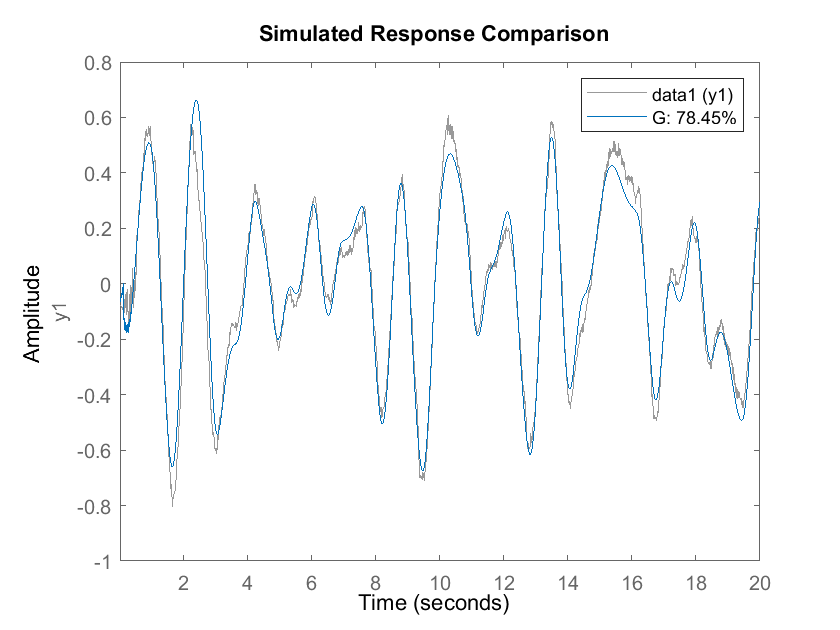

data1=detrend(data);
G=n4sid(data1,16);
figure
compare(data1,G)

## Task 8: Design a Serve Controller Using LQR Method

After fitting a model to the bicopter i/o data, we proceed with the design of a controller. In order to reduce the steady-state error to zero, we add an integrator Gi to the plant G. Then a controller is designed for the augmented plan of order n+1. The controller is designed using linear quadrati regulator (LQR) theory, where the cost function is $\int_0^\infty y^2+Ru^2dt=\int_0^\infty x^TC^TCx+Ru^2dt$. The value of $R$ is selected is set to 5. This value can be changed to design different controllers.  $Q=C^TC$ can also be replaced with more general positive definite matrix. The resulting closed-loop poles are re-used as observer poles for this n+1 model, however they were placed 2x closer to the origin (CLP/2). This location can also be modified. 

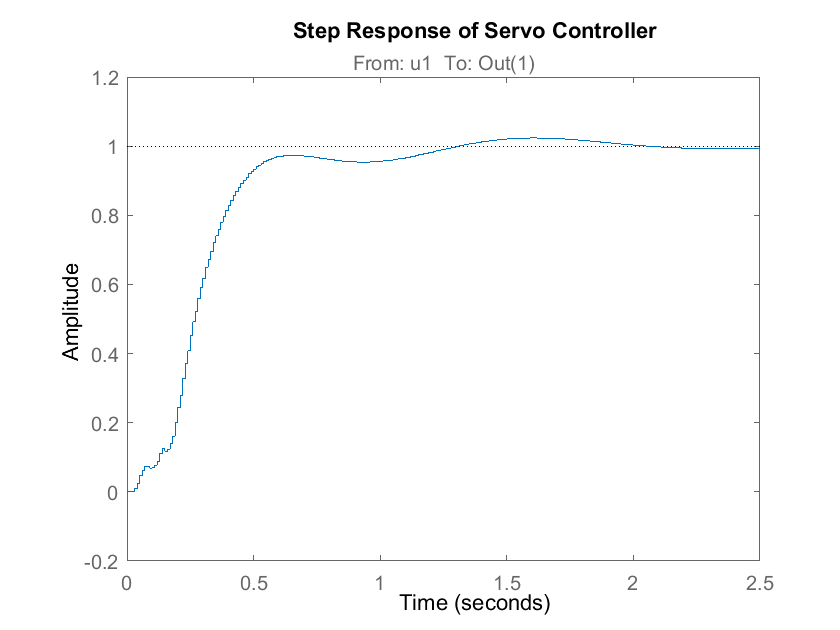

close all;
% Integrator added to the ss model
Gi=tf([0 1],[1 -1],.01);
sysi=G*Gi;
% closed loop poles
%[K,S,CLP] = dlqr(sysi.A,sysi.B,sysi.C'*sysi.C,11,0); % change 5 (R-value) for different controllers
[K,S,CLP] = dlqr(sysi.A,sysi.B,eye(17)*0.0005,.1,0); % change 5 (R-value) for different controllers
Ke =acker(sysi.A',sysi.C',CLP/2)'; % observer poles 2x closer to origin
Aoc=sysi.A-sysi.B*K-Ke*sysi.C;Boc=Ke;Coc=K;
Ci=ss(Aoc,Boc,Coc,0,0.01)*Gi; % Integrator is moved to the controller
Ci=balred(Ci,6); % reducing the order of the controller via balanced reduction 
% Design for a system with controller split in the forward path
% (integrator) and feedback path (observer-controller)
Cfb=ss(Aoc,Boc,Coc,0,0.01); % portion of controller placed in the feedback, integrator (Gi) remains in the forward path
N=1/dcgain(feedback(Gi*G,Cfb)); % pre-filter gain for a system with a controller in the feedback
step(feedback(Ci*G,1));title('Step Response of Servo Controller');shg

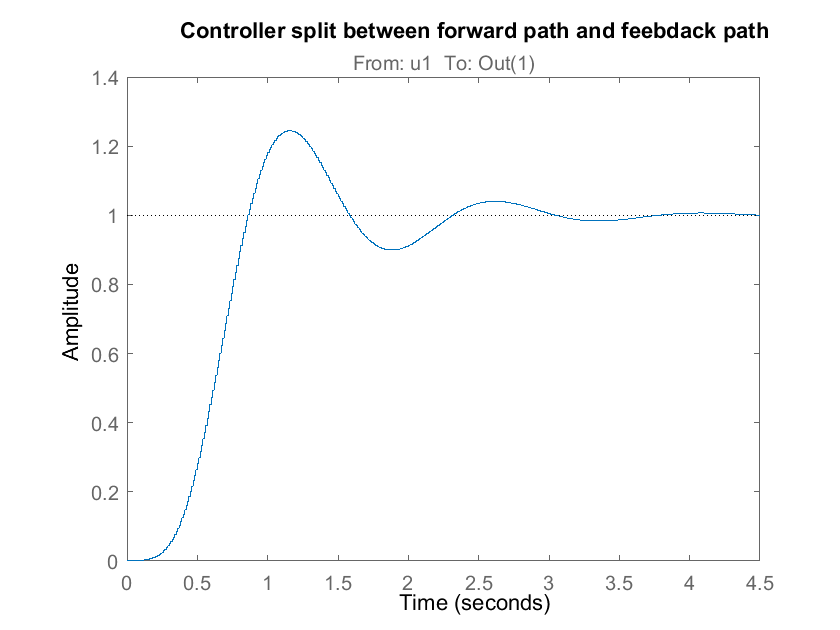

figure
step(N*feedback(Gi*G,Cfb));title('Controller split between forward path and feebdack path')

## Task 9 Test the Observer-Controller in  

Open the "**Bicopter_ClosedLoop_2022_SS.slx" **model, compile the code, and run the experiment, by runnng this section. The controller parameters are automatically transfered from the Workspace to the model. Make sure the IP address remains unchanged and **keep clear from the propellers. Remove the USB cable before running and flip the power switch to battery operation. **

tcp = tcpclient(IPADRR,25000);flush(tcp);

replacing `'172.20.10.5'` with your device's IP address.

Next, we can define an input array, which is the desired angle of the close-loop control. As an example, I have defined:

dur = 2500;
% Generate setpoint signal
Input = zeros(dur,1);
 Input(501:1000) = 0.3;
 Input(1501:2000) = -0.3;

With this, one can connect to the Arduino, send the input values, and record the response:

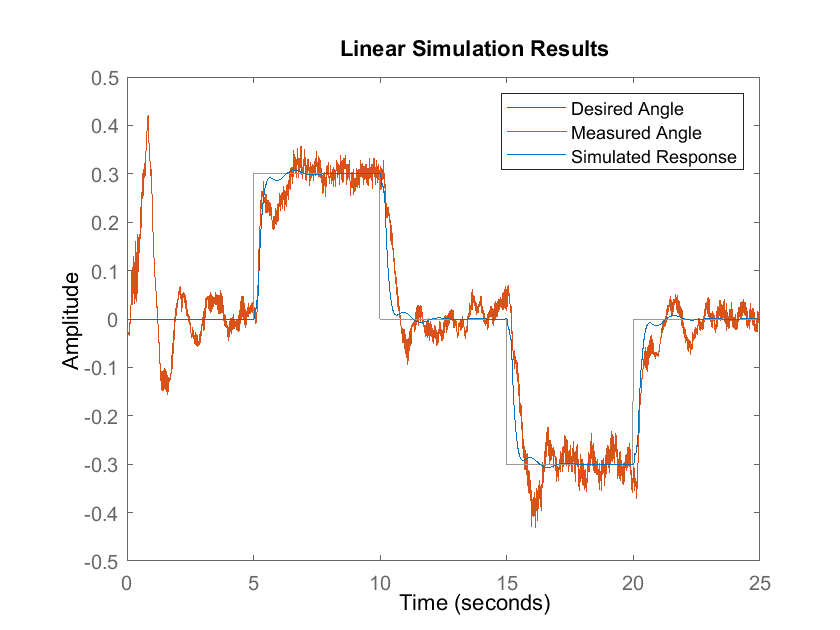

%write(tcp,[0],'single');
%pause(0.5);
flush(tcp);
write(tcp,Input,'single');
tic
en = 0;
while en == 0  % wait for the test to finish before reading back the data
  dat = read(tcp,4,'double');
   en = dat(4);
end
D = read(tcp,4*dur,'double');
Output = D(1:4:end);
Control = D(2:4:end);
SP = D(3:4:end);
en = D(4:4:end);
T_f = toc;
clear tcp

figure
Time = 0:0.01:0.01*(dur-1);
plot(Time, SP);
hold on
plot(Time, Output);
lsim(feedback(Ci*G,1),SP,Time);
legend('Desired Angle','Measured Angle','Simulated Response')

## Further Studies:

- Change the value of the Q and R to design different controllers

- Try fitting different models, such as higher order transfer functions, ARX models, n4sid, ARMAX,OE,BJ.